class1 = 'TURMER';
class2 = 'LUSMEG';

signals = {};

directoryPath = sprintf('samples/%s/syllables/%s',class1,"train");
fileList = dir(fullfile(directoryPath, '*.wav'));   
limit = numel(fileList);
for ii = 1:limit
    filePath = fullfile(directoryPath, fileList(ii).name);
    [signal,~] = audioread(filePath);
    signal = mono(signal);
    if numel(signal) < 2.4e4
        signals(size(signals,1)+1,:) = {signal};
    end
end

directoryPath = sprintf('samples/%s/syllables/%s',class2,"train");
fileList = dir(fullfile(directoryPath, '*.wav'));   
limit = numel(fileList);
for ii = 1:limit
    filePath = fullfile(directoryPath, fileList(ii).name);
    [signal,~] = audioread(filePath);
    signal = mono(signal);
    if numel(signal) < 2.4e4
        signals(size(signals,1)+1,:) = {signal};
    end
end

L = cellfun(@length,signals);
h = histogram(L);

morebins(h);
morebins(h)

xticks(0:2000:2.5e4)
xlabel('Syllable sample length')
ylabel('Frequency')
hold on
xline(14000, 'r--', 'LineWidth', 2);
hold off

[audio,fs] = audioread('samples/TROTRO/raw/XC818793.mp3');
audio = mono(audio);
audio = audio(1:3*fs);

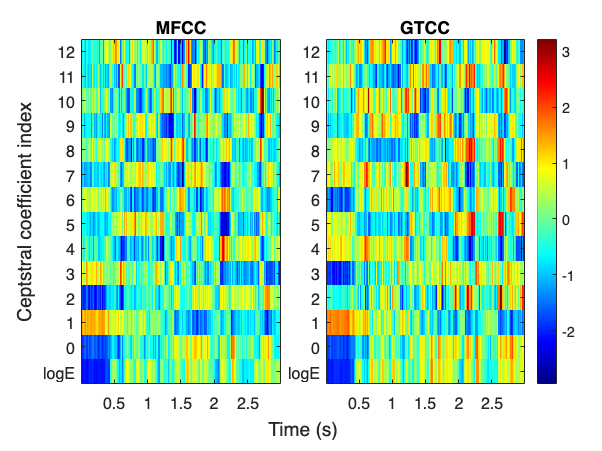

t = tiledlayout(1,2);
t.TileSpacing = "compact";

nexttile
mfcc(audio,fs)
colorbar off
ylabel ''
xlabel ''
title('MFCC')

nexttile
gtcc(audio,fs)
ylabel ''
xlabel ''
title('GTCC')

ylabel(t,'Ceptstral coefficient index')
xlabel(t,'Time (s)')

filtBank = gammatoneFilterBank([50, fs/2],64,fs);
audioOut = filtBank(audio);

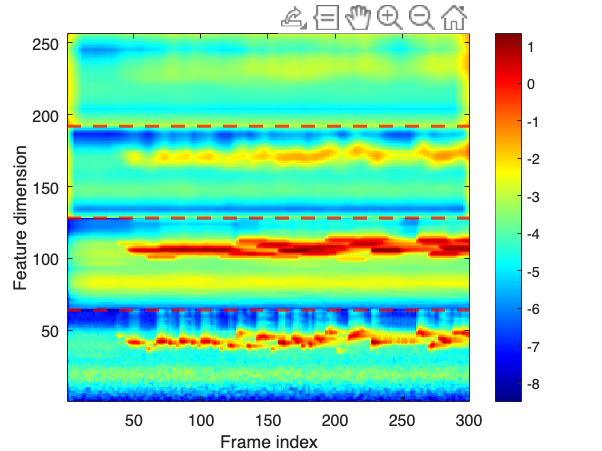

mrcgFeatures = mrcg(audioOut,fs);
figure;
imagesc(mrcgFeatures);
colormap jet;
colorbar;
ylabel('Feature dimension');
xlabel('Frame index');
yline([64,64*2,64*3],'r--','LineWidth', 2);
% title(sprintf('%s MRCG',titleText));
set(gca,'YDir','normal');